# Example 9.1: Computing entropy.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

Consider a $4 \times 4$ image whose histogram (see `p` in the following code) models the symbol probabilities in Table 9.1. 

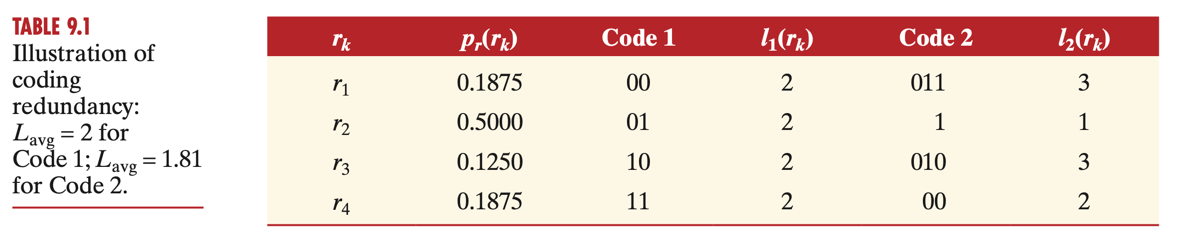

The following commands generate one such image and compute a first-order estimate of its entropy. 		

f = [119 123 168 119; 123 119 168 168];
f = [f; 119 119 107 119; 107 107 119 119]

f =    119   123   168   119
   123   119   168   168
   119   119   107   119
   107   107   119   119


p = histcounts(f(:),8); 
p = p/sum(p)

p =     0.1875    0.5000    0.1250         0         0         0         0    0.1875


h = ntrop(f)

h = 1.7806

Code 2 of Table 9.1, with $L_{\text{avg}} = 1.81$, approaches this first-order entropy estimate and is a minimal length *binary *code for image `f`. Note that gray level 107 corresponds to $r_1$ and corresponding binary codeword $011_2$ Table 9.1, 119 corresponds to $r_2$ and code $1_2$, and 123 and 168 correspond to $010_2$ and $00_2$, respectively. 